clear; clc; close all;

%% 1. CARGAR MODELO RANDOM FOREST ENTRENADO
modeloFile = 'modelo_random_forest.mat';

if isfile(modeloFile)
    data = load(modeloFile); 
    
    % Buscar automáticamente un modelo que sea un objeto con método 'predict'
    campos = fieldnames(data);
    encontrado = false;
    for i = 1:length(campos)
        candidato = data.(campos{i});
        if isobject(candidato) && ismethod(candidato, 'predict')
            modeloFinal_RF = candidato;
            encontrado = true;
            fprintf('\n✅ Modelo cargado: "%s"\n', campos{i});
            break;
        end
    end
    
    if ~encontrado
        error('❌ El archivo existe pero no contiene un modelo de clasificación válido.');
    end
else
    error('❌ No se encontró el archivo "%s". Entrena y guarda el modelo primero.', modeloFile);
end


✅ Modelo cargado: "modelo_rf"


%% 2. ANÁLISIS DE UNA IMAGEN NUEVA
[archivo, ruta] = uigetfile({'*.jpg;*.jpeg;*.png;*.tif;*.tiff', ...
    'Imágenes (*.jpg, *.jpeg, *.png, *.tif, *.tiff)'}, ...
    'Seleccione una imagen');

if isequal(archivo, 0)
    error('No se seleccionó ningún archivo. Abortando.');
end

imagenPath = fullfile(ruta, archivo);
tablaResultados = analizarImagenIndividual(imagenPath);
disp('Características extraídas de la imagen:');

Características extraídas de la imagen:


disp(removevars(tablaResultados, 'GroupCount'));

         NombreImagen          mean_Area    mean_Perimetro    mean_Circularidad    mean_IntensidadR    mean_IntensidadG    mean_IntensidadB    mean_IntensidadRGBMedia
    _______________________    _________    ______________    _________________    ________________    ________________    ________________    _______________________

    {'20190624_094236.jpg'}         92          31.741              1.1475              139.74              28.707              152.72                 107.05         
    {'20190624_094236.jpg'}       6966          309.66             0.91289              91.282              31.293              170.67                 97.749         
    {'20190624_094236.jpg'}          2            1.96     


%% 3. PREDICCIÓN Y DIAGNÓSTICO

% Verifica si el modelo tiene definidos los nombres de predictores
if isprop(modeloFinal_RF, 'PredictorNames')
    varsParaModelo = modeloFinal_RF.PredictorNames;
else
    error('El modelo cargado no contiene información sobre las variables predictoras.');
end

% Verifica que todas esas columnas estén presentes en la tabla
faltantes = setdiff(varsParaModelo, tablaResultados.Properties.VariableNames);
if ~isempty(faltantes)
    error('Faltan las siguientes columnas en la tabla para predecir: %s', strjoin(faltantes, ', '));
end

% Extraer y normalizar solo esas columnas
tablaResultados(:, varsParaModelo) = fillmissing(tablaResultados(:, varsParaModelo), 'constant', 0);
X_test = normalize(tablaResultados{:, varsParaModelo});

% Realizar predicción
[y_pred_cell, ~] = predict(modeloFinal_RF, X_test);
y_pred = categorical(y_pred_cell);

% Eliminar columna 'Tipo' si existía (para evitar conflicto)
if any(strcmp(tablaResultados.Properties.VariableNames, 'Tipo'))
    tablaResultados.Tipo = [];
end

% Construir tabla con predicciones
tablaResultados = [table(tablaResultados.NombreImagen, 'VariableNames', {'NombreImagen'}), ...
                   table(y_pred, 'VariableNames', {'Tipo'}), ...
                   tablaResultados(:, setdiff(tablaResultados.Properties.VariableNames, {'NombreImagen'}))];

% Mostrar resultados
disp('Resulatdos con predicción:');

Resulatdos con predicción:


disp(removevars(tablaResultados, 'GroupCount'));

         NombreImagen              Tipo         mean_Area    mean_Circularidad    mean_IntensidadB    mean_IntensidadG    mean_IntensidadR    mean_IntensidadRGBMedia    mean_Perimetro
    _______________________    _____________    _________    _________________    ________________    ________________    ________________    _______________________    ______________

    {'20190624_094236.jpg'}    Parasito              92            1.1475              152.72              28.707              139.74                 107.05                 31.741    
    {'20190624_094236.jpg'}    Ruido               6966           0.91289              170.67              31.293              91.282        


% Diagnóstico
numParasitos = sum(tablaResultados.Tipo == 'Parasito');
numGlobulosBlancos = sum(tablaResultados.Tipo == 'GlobuloBlanco');
if numGlobulosBlancos == 0
    razonParasitosPorGB = Inf;
else
    razonParasitosPorGB = numParasitos / numGlobulosBlancos;
end

umbralInfeccion = 0.05;
if razonParasitosPorGB >= umbralInfeccion
    estadoInfeccion = 'Muestra infectada por malaria';
else
    estadoInfeccion = 'Muestra sana';
end

fprintf('\nCantidad de parásitos: %d\n', numParasitos);


Cantidad de parásitos: 1


fprintf('Cantidad de glóbulos blancos: %d\n', numGlobulosBlancos);

Cantidad de glóbulos blancos: 17


fprintf('Razón P/GB: %.3f\n', razonParasitosPorGB);

Razón P/GB: 0.059


fprintf('Estado de la imagen: %s\n', estadoInfeccion);

Estado de la imagen: Muestra infectada por malaria


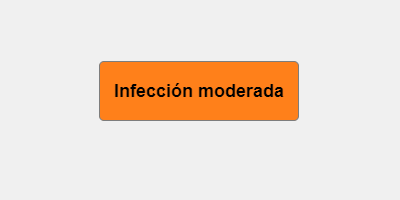


% Mostrar botón con color según diagnóstico
estado = '';
colorBtn = '';

if razonParasitosPorGB < 0.01
    estado = 'Sano';
    colorBtn = [0.2, 0.8, 0.2];  % Verde
elseif razonParasitosPorGB < 0.05
    estado = 'Sospechoso leve';
    colorBtn = [1.0, 1.0, 0.2];  % Amarillo
elseif razonParasitosPorGB < 0.1
    estado = 'Infección moderada';
    colorBtn = [1.0, 0.5, 0.1];  % Naranja
else
    estado = 'Infección severa';
    colorBtn = [1.0, 0.2, 0.2];  % Rojo
end

% Crear GUI con botón de diagnóstico
fig = uifigure('Name', 'Diagnóstico', 'Position', [100 100 400 200]);

btn = uibutton(fig, ...
    'Text', estado, ...
    'Position', [100 80 200 60], ...
    'FontSize', 18, ...
    'FontWeight', 'bold', ...
    'BackgroundColor', colorBtn, ...
    'FontColor', [0 0 0]);

Si P/GB > 0.05 --> muestra infectada de malaria // Si P/GB < 0.05 --> muestra sana

function tabla = analizarImagenIndividual(imgPath)
    [~, nombreImagen, ext] = fileparts(imgPath);
    nombreArchivo = [nombreImagen, ext];
    
    IPF = imread(imgPath);
    Imagen_FILT = im2double(IPF);    
    I_gray = rgb2gray(Imagen_FILT);

    Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
    fov_mask = segmentCellsStainBased(Imagen_mascara_gray);

    OD = -log(Imagen_FILT + 0.01);
    OD = reshape(OD, [], 3);
    W_manual = [
        0.650, 0.072, 0.707;
        0.704, 0.990, 0.707;
        0.286, 0.117, 0.000
    ];
    W = W_manual ./ vecnorm(W_manual, 2, 2);
    W = W';
    C = OD * inv(W);
    deconvolved_manual = reshape(C, size(IPF));
    Imagen_nucleos = deconvolved_manual(:,:,3);

    bw = imbinarize(Imagen_nucleos);
    Imagen_masked = bw .* fov_mask;

    imagenEcualizada = adapthisteq(I_gray);
    mascaraPortaobjetos = imbinarize(imagenEcualizada, graythresh(imagenEcualizada));
    mascaraPortaobjetos = imfill(mascaraPortaobjetos, 'holes');
    mascaraPortaobjetos = bwareafilt(mascaraPortaobjetos, 1);
    imagenEcualizada(~mascaraPortaobjetos) = 0;

    pixelesDentroFOV = imagenEcualizada(fov_mask);
    umbralOscuridad = prctile(pixelesDentroFOV, 5);
    mascaraOscuros = imagenEcualizada < umbralOscuridad;
    mascaraOscuros = mascaraOscuros & logical(fov_mask);

    areaMinimaGlobulos = 1800;
    mascaraGB = bwareafilt(mascaraOscuros, [areaMinimaGlobulos Inf]);

    elementoEstructurante = strel('disk', 15);
    mascaraGBdilatada = imdilate(mascaraGB, elementoEstructurante);

    imagenSinGB = Imagen_masked;
    imagenSinGB(mascaraGBdilatada) = 0;
    imagenSegmentable = uint8(imagenSinGB);

    umbralGlobal = graythresh(imagenSegmentable);
    mascaraOtros = imbinarize(imagenSegmentable, umbralGlobal);
    mascaraOtros = filtrar_por_tamano(mascaraOtros, 400);  

    mascaraTotal = mascaraGB | mascaraOtros;

    tabla = calcularCaracteristicas(mascaraTotal, IPF, nombreArchivo);
end

function fov_mask = segmentCellsStainBased(I)
    if size(I, 3) == 3
        I = rgb2gray(I);
    end
    level = graythresh(I);
    bw = imbinarize(I, level);
    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end
    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');
    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');
    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;
    adjusted_radius = max(circle_radius - 15, 0);
    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);
    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;
end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

function tabla = calcularCaracteristicas(mascara, imagen, nombreImagen)
    props = regionprops(mascara, 'Area', 'Perimeter', 'PixelIdxList');
    n = length(props);

    if n == 0
        tabla = table();
        return;
    end

    % Canales RGB
    R = imagen(:,:,1);
    G = imagen(:,:,2);
    B = imagen(:,:,3);

    % Inicializar vectores
    Area = zeros(n,1);
    Perimetro = zeros(n,1);
    Circularidad = zeros(n,1);
    IntensidadR = zeros(n,1);
    IntensidadG = zeros(n,1);
    IntensidadB = zeros(n,1);

    for i = 1:n
        A = props(i).Area;
        P = props(i).Perimeter;
        Area(i) = A;
        Perimetro(i) = P;

        if P > 0
            Circularidad(i) = 4 * pi * A / (P^2);
        else
            Circularidad(i) = 0;
        end

        idx = props(i).PixelIdxList;

        if isempty(idx)
            IntensidadR(i) = 0;
            IntensidadG(i) = 0;
            IntensidadB(i) = 0;
        else
            IntensidadR(i) = mean(R(idx), 'omitnan');
            IntensidadG(i) = mean(G(idx), 'omitnan');
            IntensidadB(i) = mean(B(idx), 'omitnan');
        end
    end

    IntensidadRGBMedia = mean([IntensidadR, IntensidadG, IntensidadB], 2, 'omitnan');
    IntensidadRGBMedia(isnan(IntensidadRGBMedia)) = 0;  % Extra: proteger por si acaso

    NombreImagen = repmat({nombreImagen}, n, 1);
    GroupCount = ones(n, 1);

    % Construir tabla final
    tabla = table(NombreImagen, GroupCount, ...
                  Area, Perimetro, Circularidad, ...
                  IntensidadR, IntensidadG, IntensidadB, IntensidadRGBMedia);

    % Renombrar variables según espera el modelo
    tabla.Properties.VariableNames{'Area'} = 'mean_Area';
    tabla.Properties.VariableNames{'Perimetro'} = 'mean_Perimetro';
    tabla.Properties.VariableNames{'Circularidad'} = 'mean_Circularidad';
    tabla.Properties.VariableNames{'IntensidadR'} = 'mean_IntensidadR';
    tabla.Properties.VariableNames{'IntensidadG'} = 'mean_IntensidadG';
    tabla.Properties.VariableNames{'IntensidadB'} = 'mean_IntensidadB';
    tabla.Properties.VariableNames{'IntensidadRGBMedia'} = 'mean_IntensidadRGBMedia';
end